# **MATLAB-101**

*HAZIRLAYAN: BURAK ÖZPOYRAZ - burakozpoyraz@gmail.com*

## DERS - 4

### 1) FONKSİYONLAR

Fonksiyonlar belirli girdilere göre belirli çıktılar veren yapılardır ancak her zaman girdi almak veya çıktı vermek zorunda değildirler. Fonksiyonlar, özellikle uzun programlarda karmaşıklığı azaltmak adına kullanılan çok işlevsel yapılardır.

Fonksiyonlar iki gruba ayrılırlar:

- Kullanıma hazır (built-in) fonksiyonlar

- Kullanıcı tarafından hazırlanan fonksiyonlar

#### 1.1) Kullanıma Hazır Fonksiyonlar (Built-In Functions)

MATLAB'de birçok farklı işlevi yerine getiren fonksiyon vardır. Bunlardan ilki **trigonometrik** fonksiyonlardır. Bu fonksiyonlardan bir kısmını ilk derste öğrenmiştik:

- `sin`

- `cos`

- `tan`

- `asin`

- `acos`

- `atan`

Hazır fonksiyonların bir başka sınıfı da **üstel **ve **logaritmik **fonksiyonlardır. Bu fonksiyonlardan önemli olanları da yine ilk derste öğrenmiştik:

- `exp`

- `sqrt`

- `log10`

- `log`

Bunlara ek olarak iki tabanında logaritma aşağıda verildiği gibi hesaplanabilir:

c = log2(8);

MATLAB'de tanımlı bir diğer fonksiyon sınıfı da **kompleks sayılar **ile ilgilidir. Kompleks sayılarla kullanılabilecek önemli fonksiyonları ilk derste öğrenmiştik:

- `conj`

- `real`

- `imag`

- `angle`

**Ondalıklı sayılar** ile ilgili fonksiyonları da hatırlayacak olursak:

- `floor`

- `ceil`

- `round`

Bunlara ek olarak kullanılabilecek faydalı fonksiyonlar aşağıdaki gibidir.

d = fix(4.2);
e = sign(5);

Bunlar haricinde sayılarla alakalı kullanılabilecek diğer fonksiyonlar aşağıdaki gibidir.

f = isprime(7);
g = gcd(25, 30);
h = lcm(6, 8);
i = nchoosek(5, 3);
j = factorial(5);
k = mod(8, 6);

**Vektör ve matrislerle** kullanılabilecek bazı fonksiyonları görmüştük:

- `length`

- `size`

- `numel`

- `min`

- `max`

- `mean`

- `sum`

- `prod`

- `find`

Bunlar haricinde de MATLAB'de vektör ve matrisler için kullanılabilecek çok işlevsel fonksiyonlar vardır.

vector = [1 3 -2 7];
sorted_vector = sort(vector);
flipped_vector = flip(vector);

matrix = [18 23 8 17 6;
          4 34 14 22 7;
          9 53 10 1 25;
          9 42 27 5 20];
sorted_matrix = sortrows(matrix)

**Sembolik Fonksiyonlar**

MATLAB'de matematiksel fonksiyonlar oluşturmak ve fonksiyon işlemleri yapabilmek için **sembolik fonksiyonlar** kullanılır. Şimdiye kadar hep ayrık (discrete) dizileri kullandık çünkü MATLAB'de sürekli (continuous) diziler oluşturulamaz. Ancak sembolik fonksiyonlar sayesinde sürekli matematiksel fonksiyonlar oluşturulabilir. Bunun için `syms` değişkenler tanımlanabilir. Örneğin $f(x) = x^{2} +2x + 1$ fonksiyonu aşağıdaki gibi oluşturulabilir.

syms x
f(x) = x^2 + 2 * x + 1;
f_syms = f(5);
f5 = double(f_syms);

Birden fazla bağımsız değişken ile de matematiksel fonksiyon tanımlanabilir.

syms x y
g(x, y) = x^2 + 2 * x * y + y^2;
g23 = double(g(2, 3));

Çok karmaşık fonksiyonları en sade haline getirmek için `simplify` fonksiyonu kullanılabilir.

syms x
f(x) = x^6 + 6 * x^5 + 27 * x^4 + 68 * x^3 + 135 * x^2 + 150 * x + 125;
simplify(f)

Denklemleri, eşitsizlikleri veya sistemleri çözdürmek için `solve` fonksiyonu kullanılabilir. Matematiksel denklemlerin yanında vektörleri, matrisleri veya herhangi bir değişkeni içeren herhangi bir sistem çözdürülebilir. Örneğin aşağıda verilen iki denklemin kesiştikleri noktaları solve fonksiyonunu kullanarak bulabiliriz.


$$x^{2} + 2x - y = -1$$



$$y - 7 = x$$


Bunun için aşağıdaki verilenler sırasıyla tanımlanmalıdır:

- **Bağımsız Değişken**: Yukarıdaki örnekte bağımsız değişken yalnızca $x$ değişkenidir.

- **Çözdürülecek Sistem**: Yukarıdaki sistemde çözdürülecek sistem iki denklemin kesişim noktasıdır.

- **Kısıtlar**: Yukarıdaki örnekte tek kısıt iki denklemin birbirine eşit olması durumudur.

- **Çözüm**: Tanımlanan kısıtlar ve bağımsız değişkenler kullanılarak çözüm fonksiyonu tanımlanır.

syms x
f1(x) = x^2 + 2 * x + 1;
f2(x) = x + 7;
eqn = f1 == f2;
sol_array = double(solve(eqn, x));

Birden fazla koşulu aynı anda sağlayacak çözümü bulmak için her koşulu ayrı bir denklem olarak solve fonksiyonuna vermemiz gerekmektedir. Örneğin yukarıdaki iki fonksiyonun kesiştiği noktalardan negatif olanını aşağıdaki gibi bulabiliriz.

syms x
f1(x) = x^2 + 2 * x + 1;
f2(x) = x + 7;
eqn1 = f1 == f2;
eqn2 = x < 0;
eqn_array = [eqn1, eqn2];
sol_neg = double(solve(eqn_array, x));

Birden fazla bilinmeyen de en az bilinmeyen sayısı kadar denklem verilerek çözülebilir. Örneğin aşağıdaki iki bilinmeyenli iki denklem çözmek için her bir denklemi ve bilinmeyeni solve fonksiyonuna vermemiz gerekmektedir.


$$a^{2} + 2a + b = 3$$



$$5a - 4b = 2$$


syms a b
eqn1 = a^2 + 2 * a + b == 3;
eqn2 = 5 * a - 4 * b == 2;
s = solve(eqn1, eqn2, a, b);
a_sol = double(s.a);
b_sol = double(s.b);

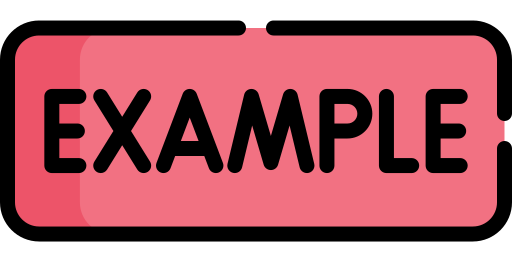

**1)** $f(x) = ax^2 + b$ fonksiyonu için aşağıdaki eşitlikler verilmiştir:

- 
$$f(x + 2) = f(x) + x + 1$$


- 
$$f(1) = 3$$


Bu eşitliklerden yola çıkarak $f(2a + 6b)$ değerini hesaplayınız ve 75'e eşit olduğunu teyit ediniz.

syms a b x
f(x) = a * x^2 + b;
eqn1 = f(x + 2) == f(x) + x + 1;
eqn2 = f(1) == 3;
s = solve(eqn1, eqn2, a, b);
a_sol = double(s.a);
b_sol = double(s.b);

f(x) = a_sol * x^2 + b_sol;
equality = double(f(2 * a_sol + 6 * b_sol)) == 75;

 

#### 1.2) Kullanıcı Tarafından Hazırlanan Fonksiyonlar

Dersin başında bahsedildiği gibi kullanım kolaylığı açısından özel fonksiyonlar tanımlanabilir. Fonksiyonlar tanımlandıkları isimle aynı isimdeki dosyaya kaydedilmelidir. Yani mesela `myfunc` isminde bir fonksiyon oluşturulursa `myfunc.m` dosyası olarak kaydedilmelidir.

**2)** Aldığı girdinin faktöriyelini hesaplayıp çıktı olarak veren fonksiyonu yazarak sonrasında 1'den 10'a kadar tüm sayıların faktöriyelini hesaplayan kodu yazınız.

factorial_vector = zeros(1, 10);
for i = 1 : 10
    factorial_vector(i) = MyFactorial(i);
end

### 2) PROBLEMLER

#### Problem - 1 / Banknot Sayar

Girdi olarak bir para değeri alıp, parayı en az banknotla elde edecek şekilde her banknottan kaçar tane olduğunu matris olarak çıktıya veren fonksiyonu oluşturunuz. Örnek olarak para değeri 359 ise çıktıda elde edilmesi beklenen matris aşağıda verildiği gibidir:


$$\matrix{
200 & 100 & 50 & 5 & 1 \cr
1 & 1 & 1 & 1 & 4
}$$


Fonksiyon sonucunda elde edilen matrisin doğru sonuç verip vermediğini, matristeki paraları toplayarak beklenen para değerine eşit olup olmadığına bakarak kontrol ediniz.

m = 359;
M = Money(m)

#### Problem - 2 / Borsa Krizi

Bir yatırımcı 113000€ parasını borsada teknoloji, ilaç ve yenilenebilir enerji hisselerine yatırmıştır. Bu yatırım sonucunda ilk yıl sonunda teknoloji hisseleri %8, ilaç hisseleri %10 ve yenilenebilir enerji hisseleri %12 oranında kazanç getirmiştir ve yatırımcı toplamda 12120€ kazanmıştır. Bu kazançtan oldukça memnun kalan yatırımcı, bir yıl sonunda elde ettiği kazancın %20'sini teknoloji, %30'unu ilaç ve kalan %50'sini de yenilenebilir enerji hisselerine yatırmayı planlamıştır. Ancak bir başka yatırımcı arkadaşının tavsiyesi üzerine kazancın tamamını yenilenebilir enerji hisselerine yatırmıştır. İkinci yıl sonunda teknoloji hisseleri %12, ilaç hisseleri %15 ve yenilenebilir enerji hisseleri %3 oranında kazanç getirmiştir ve yatırımcı toplamda 10143,6€ kazanmıştır. Yatırımcı eğer arkadaşının tavsiyesine kulak asmasaydı ne kadar daha kazanacaktı?

syms X Y Z
T = 113000;
I1 = 12120;
I2 = 10143.6;

eqn1 = X + Y + Z == T;
eqn2 = X * 0.08 + Y * 0.1 + Z * 0.12 == I1;
eqn3 = X * 0.12 + Y * 0.15 + (Z + I1) * 0.03 == I2;
s = solve(eqn1, eqn2, eqn3, X, Y, Z);

X = double(s.X);
Y = double(s.Y);
Z = double(s.Z);

I2_exp = (X + I1 * 0.2) * 0.12 + (Y + I1 * 0.3) * 0.15 + (Z + I1 * 0.5) * 0.03;
I2_loss = I2_exp - I2;

#### Problem - 3 / Kaç Basamaklı?

Girdi olarak bir pozitif tam sayı alıp, sayının kaç basamaklı olduğunu tespit ettikten sonra basamak sayısı ve tüm basamaklardan oluşan matrisi çıktıya veren fonksiyonu oluşturunuz. Örnek olarak girdi 2563 ise çıktıda elde edilmesi beklenen matris aşağıda verildiği gibidir:


$$\matrix{
\text{0} & \text{1000} & \text{100} & \text{10} & \text{1} \cr
4 & 2 & 5 & 6 & 3
}$$


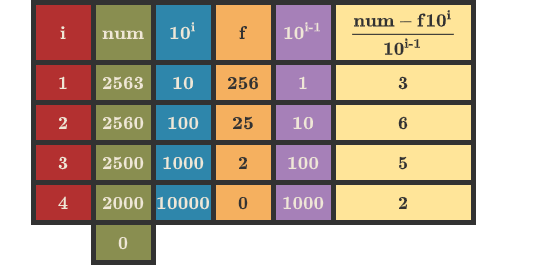

Çıktıda elde ettiğiniz matrisin doğruluğunu kontrol etmek için matristeki basamaklardan oluşan sayının beklenen sayıya eşit olup olmadığını kontrol ediniz.

num = 2563;
M = Digit(num)